# Generalized Conway's Game of Life

## 設定

- T                ：シミュレーション回数

- n                ：エリアのサイズ

- d                ：近傍の半径

- alive_min   ：近傍の生存セル数の最小値（生存）

- alive_max  ：近傍の生存セル数の最大値（生存）

- birth_min   ：近傍の生存セル数の最小値（誕生）

- birth_max  ：近傍の生存セル数の最小値（誕生）

- movie        ：動画の表示の有無

- resize        ：保存画像のリサイズの有無


%Parameters
T = 1000;
n = 1000;
d = 29;
alive_min = (2*d+1)^2 *0.132;
alive_max = (2*d+1)^2 *0.529;
birth_min = (2*d+1)^2 *0.5017; 
birth_max = (2*d+1)^2 *0.6933;
movie = true;
resize = true;

## 実行

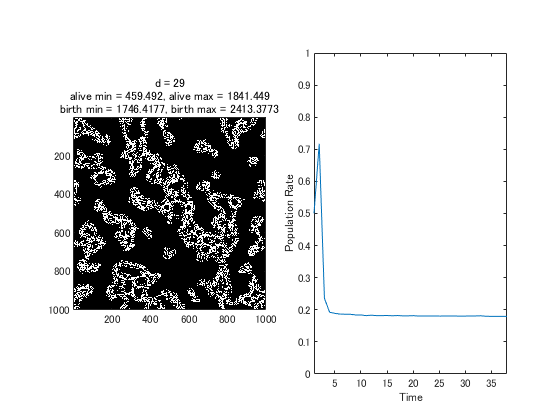

M = rand(n) > 0.5;

alive = zeros(T+1,1);
alive(1) = sum(M,"all");

tic
for t = 1:T
    %Visualize
    if movie == true
        clf
        tiledlayout(1,2,"TileSpacing","compact")
        nexttile;
        image(M*255);    colormap gray 
        pbaspect([1 1 1]);
        title(["d = "+num2str(d), ...
               "alive min = "+num2str(alive_min)+", alive max = "+num2str(alive_max) ...
               "birth min = "+num2str(birth_min)+", birth max = "+num2str(birth_max)])
        nexttile;
        plot(alive(1:t)./n^2);
        xlim([-inf inf]);
        ylim([0 1]);
        xlabel("Time");
        ylabel("Population Rate")
        drawnow
    end
    
    A = ones(2*d+1);
    A(d+1,d+1) = 0;

    temp = conv2(padarray(M,[d,d],0,'circular'),A,"same");
    S = temp(d+1:n+d,d+1:n+d);
    M_next = M.*(alive_min<=S).*(S<=alive_max)+...
        (1-M).*(birth_min<=S).*(S<=birth_max);
    
    alive(t+1) = sum(M_next,"all");
    
    if sum(abs(M-M_next),"all") == 0
        break
    end
    
    M = M_next;
end

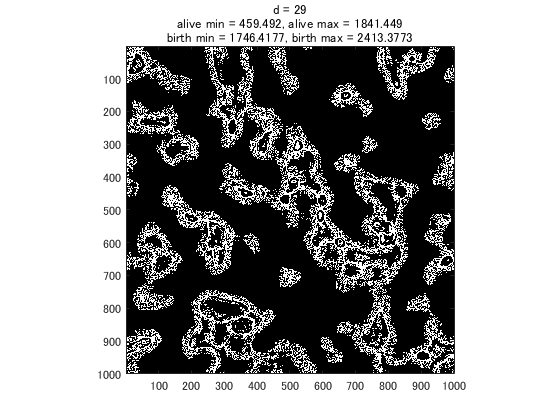

clf
image(M*255);    colormap gray 
pbaspect([1 1 1]);
title(["d = "+num2str(d), ...
       "alive min = "+num2str(alive_min)+", alive max = "+num2str(alive_max) ...
       "birth min = "+num2str(birth_min)+", birth max = "+num2str(birth_max)])

imwrite(imresize(M*255,[1024,1024],"nearest"),"result.png");